%Test 1: sample images

load testPersist.mat -mat
% raw_data = magic(25)./max(magic(25));
raw_data = persist_image;


template = ones(4,4);
offset = 6;

%trim data to avoid edge case
data = raw_data(1+offset:end-offset,1+offset:end-offset);

%performs correlation
[row, col] = tracking(data, template);

%plot image
figure(28)
imagesc(raw_data)

%overlays onto figure(27)
hold on;
% x over target
plot(col+offset, row+offset, '+', 'MarkerSize',20, 'LineWidth', 2, 'Color', 'red')
% circle over target
%     plot(track_col, track_row, 'o', 'MarkerSize',50, 'LineWidth', 2, 'Color', 'red')
hold off;

%remove max values for second target tracking
data(row-offset:row+offset, col-offset:col+offset) = 0;


[row, col] = tracking(data, template);


%overlays onto figure(27)
hold on;
% x over target
plot(col+offset, row+offset, 'x', 'MarkerSize',20, 'LineWidth', 2, 'Color', 'red')
% circle over target
%     plot(track_col, track_row, 'o', 'MarkerSize',50, 'LineWidth', 2, 'Color', 'red')
hold off;




%Test 2 edge cases

load trackingTestImages.mat -mat
raw_data = image;



template = ones(4,4);
offset = 6;

%trim data to avoid edge case
data = raw_data(1+offset:end-offset,1+offset:end-offset);

imagesc(data)

%performs correlation
[row, col] = tracking(data, template);

%plot image
figure(28)
imagesc(raw_data)

%overlays onto figure(27)
hold on;
% x over target
plot(col+offset, row+offset, '+', 'MarkerSize',20, 'LineWidth', 2, 'Color', 'red')
% circle over target
%     plot(track_col, track_row, 'o', 'MarkerSize',50, 'LineWidth', 2, 'Color', 'red')
hold off;

%remove max values for second target tracking
data(abs(row-offset):row+offset, abs(col-offset):col+offset) = 0;

% 
% [row, col] = tracking(data, template);
% 
% 
% %overlays onto figure(27)
% hold on;
% % x over target
% plot(col+offset, row+offset, '+', 'MarkerSize',20, 'LineWidth', 2, 'Color', 'red')
% % circle over target
% %     plot(track_col, track_row, 'o', 'MarkerSize',50, 'LineWidth', 2, 'Color', 'red')
% hold off;


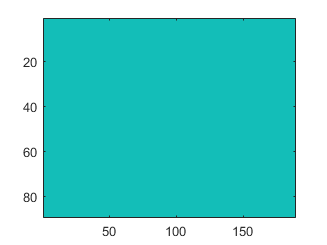

%Test 3 edge cases

load trackingTestImages.mat -mat
raw_data = image2;


template = ones(4,4);
offset = 6;
remove_offset=6;

%trim data to avoid edge case
data = raw_data(1+offset:end-offset,1+offset:end-offset);

imagesc(data)

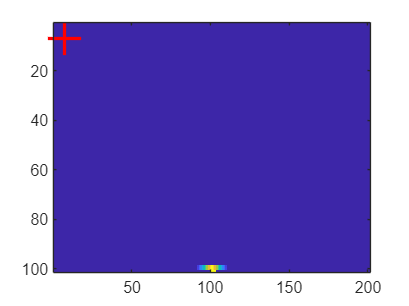


%performs correlation
[row, col] = tracking(data, template);

%plot image
figure(28)
imagesc(raw_data)

%overlays onto figure(27)
hold on;
% x over target
plot(col+offset, row+offset, '+', 'MarkerSize',20, 'LineWidth', 2, 'Color', 'red')
% circle over target
%     plot(track_col, track_row, 'o', 'MarkerSize',50, 'LineWidth', 2, 'Color', 'red')
hold off;


%remove max values for second target tracking
data(abs(row-offset):row+offset, abs(col-offset):col+offset) = 0;

% 
% [row, col] = tracking(data, template);
% 
% 
% %overlays onto figure(27)
% hold on;
% % x over target
% plot(col+offset, row+offset, '+', 'MarkerSize',20, 'LineWidth', 2, 'Color', 'red')
% % circle over target
% %     plot(track_col, track_row, 'o', 'MarkerSize',50, 'LineWidth', 2, 'Color', 'red')
% hold off;
